# EE 523 Power System Stability and Control Algorithms

### Preamble and Control Inputs

tic;
if strcmp(getenv('USERNAME'), 'aryan')
    cd C:\Users\aryan\Documents\documents_general\dablab_files\ee521_and_ee523
end

you may continue as usual

addpath functions\
systemName = "ieee11-caseTwo-"

systemName = "ieee11-caseTwo-"

powerFlowMethod =  "NRPF" 

powerFlowMethod = "NRPF"

modelType = "Type2" %Synchronous Machine Model Type

modelType = "Type2"

useReducedLoadsForPowerFlow = true; %only needed if Type 2 or 3
displayYGen = false; %Show YGen
displayYNet = false; %Show YNet
displayYBus = false;
saveYBus = true;
saveYGenMatrices = true; %Save YNet, Ygr, Yrg, Yrr, YGen
showInternalMatrices = false; %Show Ygg, Ygr, Yrg, Yrr
numIterations = 20; %I don't wait for the system to converge, 
printPowerFlowConvergenceMessages = false;
% neither do I care if the system converges earlier.
toleranceLimit = 1e-3; %mean of absolute values of 
% corrections should be less than this for convergence to be achieved.
displayRawData = false;
displayRawDataForYNet = false;
displayTables = true; %show busData, branchData ybus, 
% basically data structures which are not the final output.
saveBusDataAndBranchData = true;
saveBusDataAndBranchDataNet = true;
printJacobians = false  ; %Print Jacobians during NRPF iterations? Does not work if displayTables is off.
printMismatches = false; %Print Mismatches during NRPF iterations? Does not work if displayTables is off.
printCorrections = false;
disableTaps = false; %Disable Tap-changers when commputing YBus?
showPlots = false;
displayResults = false;
reducedBranchColumnsCDFReading = true; 
showImages = true; %might add iteration specific images later. 
verboseCDFReading = false; %Will give a verbose output when reading CDF files.
MVAb = 100; %Currently the same for all systems in database.

#### Housekeeping.

folder_rawData = "rawData/"; %location of CDF .txt file for the system
file_rawData = strcat(folder_rawData, systemName, "cdf.txt"); %Exact location of CDF .txt file for the system
folder_processedData = "processedData/";
% Should configure it to be read from the CDF file later.
latex_interpreter %for LaTeX typesetting in plots

if contains(systemName, 'ieee11')
    systemName1 = 'ieee11';
else
    systemName1 = systemName;
end

### Read CDF file and store the data in neat MATLAB `tables: busData `and `branchData`.

[busData, branchData, N, numBranchNet] = ...
    readCDF(file_rawData, reducedBranchColumnsCDFReading, verboseCDFReading);

Optionally display the system data.

if displayRawData
    displayRawDataAsTables(busData, branchData, N, numBranchNet);
end
if saveBusDataAndBranchData
    fileType = '.csv';
    filenameBusData = strcat(folder_processedData, systemName1, "/busData", fileType);
    writetable(busData, filenameBusData);
    filenameBranchData = strcat(folder_processedData, systemName1, "/branchData", fileType);
    writetable(branchData, filenameBranchData);
end

### Extract $Y_{Bus}$,  Adjacency List $E$ from the `branchData table `for Type I OR Make $Y_{Bus}$ (reduced loads only), $Y_{Net}$, $Y_{Gen}$ for Type II and Type III models.

### Then Run Newton Raphson Power Flow and obtain a steady state snapshot of the system variables $P_i, Q_i, V_i, \delta_i$ $\forall$ buses $i \in [1, N], i \in \mathbb{N}$

[~, ~, ~, ~, ...
        ~, listOfPVBuses, ~, nPV, ...
        ~] = initializeVectors(busData, MVAb);

#### Synchronous Machine Parameters

kVB = 230;
kVB_Gen = 20;
kVB_Gen_side = 20;
MVAb_Gen = 900;

Xd_prime = 0.3* ones(nPV+1, 1) * (MVAb/MVAb_Gen) * (kVB_Gen/kVB_Gen_side)^2;
Xq_prime = 0.55* ones(nPV+1, 1) * (MVAb/MVAb_Gen) * (kVB_Gen/kVB_Gen_side)^2; 
Xq = 1.7* ones(nPV+1, 1) * (MVAb/MVAb_Gen) * (kVB_Gen/kVB_Gen_side)^2; 
Xd = 1.8* ones(nPV+1, 1) * (MVAb/MVAb_Gen) * (kVB_Gen/kVB_Gen_side)^2;
Tq0_prime = 0.4 * ones(nPV+1, 1);
Td0_prime = 8.0 * ones(nPV+1, 1);
w_s = 2*pi*60;
H = [6.5; 6.5; 6.175; 6.175];
K_D = 2*ones(nPV+1, 1);
k_A = 50*ones(nPV+1, 1);
T_A = 0.05*ones(nPV+1, 1);
EfdMax = 2.0*ones(nPV+1, 1);
Efdmin = 0.0*ones(nPV+1, 1);
VRmin = -4*ones(nPV+1, 1);
VRMax = 4*ones(nPV+1, 1);
Tsg = 100*ones(nPV+1, 1);
Ksg = 1*ones(nPV+1, 1);
PsgMax = 1*ones(nPV+1, 1);
Psgmin = 0*ones(nPV+1, 1);
R = 5*1/100*ones(nPV+1, 1);

if ~strcmp(modelType, "Type1")
    X_prime = 0.5* (Xd_prime + Xq_prime);
    display(X_prime);

    [busDataNet, busDataReducedLoads, busDataGen, branchDataNet, NNet, numBranchNet] = ...
        modifyForYNet(busData, branchData, N, ...
        numBranchNet, listOfPVBuses, nPV, ...
        X_prime, MVAb, displayRawDataForYNet);

    if saveBusDataAndBranchDataNet
        fileType = '.csv';
        filenameBusDataNet = strcat(folder_processedData, systemName1, "/busDataNet", fileType);
        writetable(busData, filenameBusData);
        filenameBranchDataNet = strcat(folder_processedData, systemName1, "/branchDataNet", fileType);
        writetable(branchDataNet, filenameBranchDataNet);
    end

    [ybus, BMatrix, E, PSpecified, QSpecified, V, delta, listOfPQBuses, listOfPVBuses, nPQ, nPV, listOfNonSlackBuses] = generateYBusForType2(useReducedLoadsForPowerFlow, busData, busDataReducedLoads, branchData, MVAb);
    
    [yNet, ~, ~, ~, ~, EdgesNet] = ybusGenerator(busDataNet, branchDataNet);

    [yGen, BMatrixGen, EdgesGen, listOfResidualBuses] = constructYGen(yNet, listOfPVBuses, NNet, displayYNet, showInternalMatrices, displayYGen, saveYGenMatrices);
    
    [P, Q, V, delta] = solveForPowerFlow(PSpecified, QSpecified, V, delta, ybus, BMatrix, E, nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, numIterations, toleranceLimit, powerFlowMethod, displayTables, printJacobians, printMismatches, printPowerFlowConvergenceMessages);
    
else
    [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData);

    [PSpecified, QSpecified, V, delta, ...
        listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
        listOfNonSlackBuses] = initializeVectors(busData, MVAb);

    [P, Q, V, delta] = solveForPowerFlow(PSpecified, QSpecified, V, delta, ybus, BMatrix, E, nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, numIterations, toleranceLimit, powerFlowMethod, displayTables, printJacobians, printMismatches, printPowerFlowConvergenceMessages);
end

X_prime =     0.0472
    0.0472
    0.0472
    0.0472


Convergence using NRPF achieved in 4 iterations.


P_C = P(listOfGenBuses);

saveAndDisplayYBus(ybus, N, displayYBus, saveYBus, folder_processedData, systemName1);

### Compare obtained snapshot values of $V_i$ and $\delta_i$ against the ones given in the CDF file.

resultTable = displayPowerFlowResults(P, Q, V, delta, displayResults);
plotPowerFlowResults(showPlots, V, busData, systemName, powerFlowMethod, delta);

### Post-Powerflow

listOfGenBuses = [1; listOfPVBuses];

P_i_Gen = P(listOfGenBuses);
Q_i_Gen = Q(listOfGenBuses);
S_i_Gen = P_i_Gen + 1i*Q_i_Gen;

PGValues = P_i_Gen + busData.PL(listOfGenBuses)/MVAb;
PmType3 = PGValues;
QGValues = Q_i_Gen + busData.QL(listOfGenBuses)/MVAb;
SGValues = PGValues + 1i*QGValues;

ViVals = V(listOfGenBuses);
Vi2Vals = ViVals(listOfPVBuses);
delta_i = delta(listOfGenBuses);
delta_i2 = delta_i(listOfPVBuses);

V_ref = busData.Vset(listOfGenBuses);

% Vi = V(listOfGenBuses);
delta_i = delta(listOfGenBuses);
[Vi_CartesiansReal, Vi_Cartesian_Imag] = pol2cart(delta_i, ViVals);
V_Gen_Cartesian = Vi_CartesiansReal + 1i*Vi_Cartesian_Imag;
I_Gen = conj(SGValues./V_Gen_Cartesian);
EprimeCartesian = V_Gen_Cartesian + 1i*X_prime.*I_Gen;
[thetaVals, E_primeVals] = cart2pol(real(EprimeCartesian), imag(EprimeCartesian));
rowNamesGeneratorBuses = arrayfun(@(i) sprintf('Gen %d', i), 1:nPV+1, 'UniformOutput', false);

resultGen = array2table([E_primeVals, thetaVals], 'VariableNames', {'E''', 'theta'}, 'RowNames', rowNamesGeneratorBuses)

resultGen = 4×2 table
               E'        theta  
             ______    _________

    Gen 1    1.1332      0.29985
    Gen 2    1.0837       0.1278
    Gen 3    1.1401    -0.064742
    Gen 4    1.1068     -0.23371


theta = sym('theta', [nPV+1, 1]);
theta2 = theta(listOfPVBuses);
omega = sym('omega', [nPV+1, 1]);
omega2 = omega(listOfPVBuses);

H2 = H(listOfPVBuses);
K_D2 = K_D(listOfPVBuses);
Xd_prime2 = Xd_prime(listOfPVBuses);
Xq_prime2 = Xq_prime(listOfPVBuses);
Xq2 = Xq(listOfPVBuses);
Xd2 = Xd(listOfPVBuses);
Tq0_prime2 = Tq0_prime(listOfPVBuses);
Td0_prime2 = Td0_prime(listOfPVBuses);

V_ref2 = V_ref(listOfPVBuses);

PG = sym('P_G', [nPV+1, 1]);
Eq_primeSymbols = arrayfun(@(i) sprintf('E_prime_q%d', i), 1:nPV+1, 'UniformOutput', false);
Eq_prime = str2sym(Eq_primeSymbols');
Eq_prime2 = Eq_prime(listOfPVBuses);
Ed_primeSymbols = arrayfun(@(i) sprintf('E_prime_d%d', i), 1:nPV+1, 'UniformOutput', false);
Ed_prime = str2sym(Ed_primeSymbols');
Ed_prime2 = Ed_prime(listOfPVBuses);
Vd = ViVals.*sin(theta - delta_i);
Vd2 = Vd(listOfPVBuses);
Vq = ViVals.*cos(theta - delta_i);
Vq2 = Vq(listOfPVBuses);
Id = (Eq_prime - Vq)./Xd_prime;
Id2 = Id(listOfPVBuses);
Iq = (Ed_prime - Vd)./(-Xq_prime);
Iq2 = Iq(listOfPVBuses);
Pm = sym('P_m', [nPV+1, 1]);
% Pm = Vd.*Id + Vq.*Iq;
% Pm2 = Pm(listOfPVBuses);
 


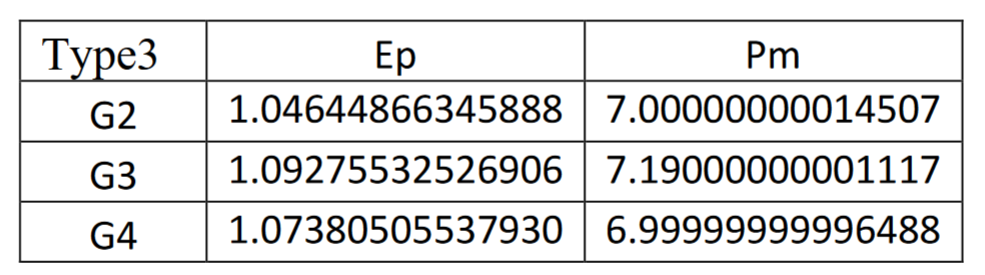

% E_primeValsOfficial = [1.10; 1.04644866345888; 1.09275532526906; 1.07380505537930];
if strcmp(modelType, 'Type3')
    PG = generateSymbolicPowerFlowEquations(listOfGenBuses, PG, yGen, E_primeVals, EdgesGen, theta);
    theta2Vals = thetaVals(listOfPVBuses);

elseif strcmp(modelType, 'Type2')
    E_prime = sqrt(Eq_prime.^2 + Ed_prime.^2);
    gamma = atan(Eq_prime./Ed_prime) + theta - pi/2
    PG = generateSymbolicPowerFlowEquations(listOfGenBuses, PG, yGen, E_prime, EdgesGen, gamma);
else
    error('Type 1 NOT modeled!');
end

$$gamma = \left(\begin{array}{c} \theta_{1}+\mathrm{atan}\left(\frac{{E^{\prime }}_{\mathrm{q1}}}{{E^{\prime }}_{\mathrm{d1}}}\right)-1.5708\\ \theta_{2}+\mathrm{atan}\left(\frac{{E^{\prime }}_{\mathrm{q2}}}{{E^{\prime }}_{\mathrm{d2}}}\right)-1.5708\\ \theta_{3}+\mathrm{atan}\left(\frac{{E^{\prime }}_{\mathrm{q3}}}{{E^{\prime }}_{\mathrm{d3}}}\right)-1.5708\\ \theta_{4}+\mathrm{atan}\left(\frac{{E^{\prime }}_{\mathrm{q4}}}{{E^{\prime }}_{\mathrm{d4}}}\right)-1.5708 \end{array}\right)$$


PG2 = PG(listOfPVBuses); 

if strcmp(modelType, 'Type3') 
    PG_computedUsingYGen = array2table(double(subs(PG, theta, thetaVals)), 'VariableNames', {'P_G'}, 'RowNames', rowNamesGeneratorBuses)
end

Pm2Type3 = PmType3(listOfPVBuses);

ode_theta = diff(theta) == (omega-1)*w_s;
ode_theta2 = ode_theta(listOfPVBuses);
ode_thetaEquilibrium = 0 == rhs(ode_theta);
ode_thetaEquilibrium2 = ode_thetaEquilibrium(listOfPVBuses);
omega2Sols = struct2cell(solve(ode_thetaEquilibrium2, omega2));
omega2Vals = double([omega2Sols{:}])';

if strcmp(modelType, 'Type3')
    ode_omegaType3 = diff(omega) == (PmType3 - PG - K_D.*(omega - 1))*0.5./H;
    ode_omega2Type3 = diff(omega2) == (Pm2Type3 - PG2 - K_D2.*(omega2 - 1))*0.5./H2;
    ode_Type3 = [rhs(ode_theta2); rhs(ode_omega2Type3)];

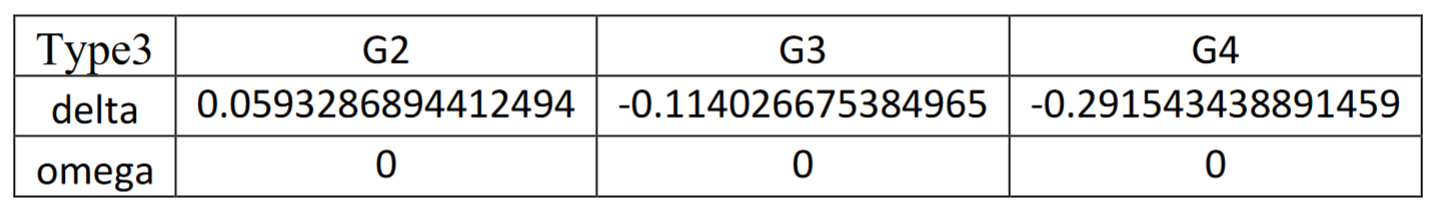

    % theta2OfficialVals = [0.0593286894412494; -0.114026675384965; -0.291543438891459];

    ode_Type3_computed = subs(ode_Type3, [theta; omega2], [thetaVals; omega2Vals]);
    J_Type3 = jacobian(ode_Type3, [theta2; omega2]);
    Je_Type3 = double(subs(J_Type3, [theta; omega2], [thetaVals; omega2Vals]));
    [Vright3, D3, W3] = eig(Je_Type3);
    lambdas3 = diag(D3);
    display(lambdas3);
    W_T3 = W3';
    p3 = Vright3*W_T3;
    for i = 1:size(p3, 1)
        p3(i, :) = p3(i, :)/max(abs(p3(i, :)));
    end
    display(p3);
elseif strcmp(modelType, 'Type2')
    fprintf('he he');
    ode_omegaType2 = 0.5*H.*(Pm - PG - K_D.*(omega - 1))
    ode_omega2Type2 = ode_omegaType2(listOfPVBuses);
    Id = sym('I_d', [nPV+1, 1]);
    Iq = sym('I_q', [nPV+1, 1]);
    for i = listOfGenBuses'
        Id(i) = 0;
        Iq(i) = 0;
        for k = EdgesGen{i}
            Id(i) = Id(i) - abs(yGen(i, k)*E_prime(i)).*sin( angle(yGen(i, k)) + gamma(k) - theta(i));
            Iq(i) = Iq(i) + abs(yGen(i, k)*E_prime(i)).*cos( angle(yGen(i, k)) + gamma(k) - theta(i));
        end
    end
    Id2 = Id(listOfPVBuses);
    Iq2 = Iq(listOfPVBuses);
    V_i = (Ed_prime + Iq.*Xq_prime).*sin(theta - delta_i);
    V_R = sym('V_R', [nPV+1, 1]);
    V_R_dot = 1./T_A.*(-V_R + k_A.*(V_ref - V_i));
    % disp(V_R_dot)
    % V_R_timeDerivative = nonWindupAVR(V_R, V_R_dot, VRMax, VRmin);
    % ode_VR = diff(V_R) == V_R_timeDerivative;
    ode_VR = diff(V_R) == V_R_dot
    ode_VREquilibrium = rhs(ode_VR) == 0;
    % disp(ode_VR)
    % Efd = windupAVR(V_R, EfdMax, Efdmin);
    Efd = V_R;
    % disp(Efd)
    P_m_dot = 1./Tsg.*( -Pm + Ksg.*(P_C - 1./R.*(omega - w_s)) );
    disp(P_m_dot);
    ode_Pm = diff(Pm) == P_m_dot;
    ode_PmEquilibrium = rhs(ode_Pm) == 0;
    ode_Eqprime = diff(Eq_prime) == 1./Td0_prime.*(-Eq_prime - (Xd - Xd_prime).*Id + Efd)
    ode_EqprimeEquilibrium = rhs(ode_Eqprime) == 0;
    ode_Edprime = diff(Ed_prime) == 1./Tq0_prime.*(-Ed_prime + (Xq - Xq_prime).*Iq)
    ode_EdprimeEquilibrium = rhs(ode_Edprime) == 0;

    ode_Type2 = [ode_thetaEquilibrium; ode_omegaType2; ode_EqprimeEquilibrium; ode_EdprimeEquilibrium; ode_VREquilibrium; ode_PmEquilibrium];
    disp(ode_Type2)
    
    odeType2Sols = struct2cell(vpasolve(ode_Type2, [theta; omega; Eq_prime; Ed_prime; V_R; Pm]));
    odeType2Vals = double([odeType2Sols{:}])'
else
    error('Type 1 NOT modeled!');
end

he he

$$\left(\begin{array}{c} 75.4712-0.2000\,\omega_{1}-0.0100\,P_{\mathrm{m1}}\\ 75.4682-0.2000\,\omega_{2}-0.0100\,P_{\mathrm{m2}}\\ 75.4701-0.2000\,\omega_{3}-0.0100\,P_{\mathrm{m3}}\\ 75.4682-0.2000\,\omega_{4}-0.0100\,P_{\mathrm{m4}} \end{array}\right)$$

odeType2Vals = 1.0e+03 *

    0.0094
    0.0406
   -0.4842
    0.0465
    0.0010
    0.0010
    0.0010
    0.0010
    0.0057
    0.0113


# Have a nice day! 

In case you encounter a Java Heap Memory error, delete the above gif, or go to `Preferences->General->Java Heap Memory` and increase the allocated size.